Reade shape file of ground truth 



clearvars
load('cmap_mat.mat')
Site='sdeDavid';
Plots_Array= load(['Plots_Array_watershed_hohoba_sdeDavid.mat']).Plots_Array;
PathName=(['C:\Users\Stav\Desktop\school\2\Research\hohoba\results\plot\plot_']);
DroneLog.datetime_utc.Format = 'hh:mm';
Alltemperatures = [];
All_Plots_Data=table();
% Change the path to the location in your computer
Big_image_path=(['C:\Users\Stav\Desktop\school\2\Research\hohoba\trimSegment&Featuers\images\Mosaics\Sde_David_2022-06-29_FLIR']);
tfw_file=strcat(Big_image_path,'.tfw');
tif_file=strcat(Big_image_path,'.tif');
tif_file=double(imread(tif_file));
tfwBigImage=worldfileread(tfw_file,'planar',size(tif_file));
Differentiate = 90;
Malfunctions = readtable(['C:\Users\Stav\Desktop\school\2\Research\hohoba\sdeDavid_Data.csv']);


%Differentiate = 42;
%theta = -94; % to rotate 90 counterclockwise
%R = [cosd(theta) -sind(theta); sind(theta) cosd(theta)];

for plot_num=1:1%size(Plots_Array,1) 
    clearvars -except plot_num Plots_Array cmap_mat Site Plot_path PathName director ...
        Malfunctions All_Plots_Data tfwBigImage Differentiate DroneLog Meteorological_Data Alltemperatures R
        if (plot_num == 1 || plot_num ==5 )
            plot_mask=[Plots_Array{plot_num,1}];
            plot_name = char(Plots_Array{plot_num,2}); 
            tfw_file=strcat([PathName plot_name],'.tfw');
            tif_file=strcat([PathName plot_name],'.mat');
            tif_file=load(tif_file).tir_mask;
            tfw=worldfileread(tfw_file,'planar',size(tif_file));
            
            Plots_Malfunctions = Malfunctions((plot_name == char(Malfunctions.Plot)),:);
            [row_malf,col_malf] = map2pix(tfw,Plots_Malfunctions.Longitude,Plots_Malfunctions.Latitude);%y,x
            Plots_Malfunctions.Latitude=row_malf;
            Plots_Malfunctions.Longitude=col_malf;
     
            
            val= newtir(find(newtir>0));
            maxT= prctile(val,99);
            minT=prctile(val,5);
        
            I=logical(plot_mask);
            BW = bwpropfilt(I,'Area',[30 inf],4);
            
            BW2 = imfill(BW,8,'holes');%binary image after cleanning hole
            CC = bwconncomp(BW2);
            Trees=struct2table(regionprops(CC,'PixelIdxList','Area','FilledImage','Centroid','BoundingBox','Orientation','MajorAxisLength','MinorAxisLength'));
            diameters = mean([Trees.MajorAxisLength Trees.MinorAxisLength],2);
            Trees.MajorAxisLength = diameters;
            %R*Trees.Centroid(1,:)'
            %A = R*Trees.Centroid'
            %A = A'
          
            Trees= removevars(Trees,{'MinorAxisLength'});
            Trees.CentroidX=Trees.Centroid(:,1);
            Trees.CentroidY=Trees.Centroid(:,2);
            %Trees.CentroidXRot =A(:,1);
            %Trees.CentroidYRot =A(:,2);
        
            Trees=splitvars(Trees,"BoundingBox");
            Trees=removevars(Trees,{'Centroid'});
            dataWithRows = table('Size',[size(Trees,1),size(Trees,2)+2],...
             'VariableTypes',{'double','double','double','double','double','double','double','cell','cell','double','double','int8','int8'},...
              'VariableNames',{'Area','BoundingBox_X','BoundingBox_Y','BoundingBox_Width','BoundingBox_Height','diameters','Orientation','FilledImage','PixelIdxList','CentroidX','CentroidY','rownum','Tree_num'});
            %Trees.CentroidYRot = R.*Trees.CentroidY';
            row_num = 1;
            amount = 0;
            first_tree = 1;
            
            plot_new=double(BW2.*tif_file);
            %plot_new = padarray(plot_new,[1000 1000],"replicate","both");
        
            %plot_new=imrotate(plot_new,-94,'crop');
        
            figure()
            imshow(plot_new, [minT-1 maxT]);
            colormap(cmap_mat);
            colorbar(); 
         
            filteredData=Trees;
            sortedData=filteredData;
            while (~isempty(sortedData))   
                if  row_num >1
                 filteredData= sortedData;
                end
                sortedData = sortrows(filteredData,["CentroidY",'CentroidX'],{'descend','descend'});
                longtitDelta = (sortedData{1:1,11}-sortedData{1:end,11});%Y
                latitDelta = (sortedData{1:1,10}-sortedData{1:end,10});%X
                angle=atand(longtitDelta./latitDelta);
                angle(find(isnan(angle))) = 0;
                sortedData.angle = angle;
                abs(diff(sortedData.angle));
                sortedData.angle(1:end-1) = abs(diff(sortedData.angle));
                last_tree = find((sortedData.angle > Differentiate),1,'first');
                
                if (isempty(last_tree))
                 last_tree = size(sortedData,1);% If ther is no more rows founded, the last tree is as the length of the left sorted data  
                end
                amount=amount+last_tree;
                dataRows=sortedData(1:last_tree,1:end-1);
                dataRows = sortrows(dataRows,'CentroidX','descend');
                dataRows.rownum = repelem(row_num,last_tree)';
                dataRows.Tree_num=(1:last_tree)';
                dataWithRows(first_tree:amount,1:size(Trees,2)+2) = dataRows;
                
                
                sortedData = sortedData(last_tree+1:end, :);
                row_num = row_num+1;
                first_tree= amount+1;
           
            end  
            %{ 
    %     L= bwlabel(BW2,4); 
    %     figure()
    %     vislabels(L);
    % 
    %     filename=[director 'Plots\Segmentation\watershed\labels\' plot_name '.png'];
    %     saveas(gcf,filename)
    
        median_Plot=median(plot_new((plot_new>0)));
        mean_Plot=mean(plot_new((plot_new>0)));
        STD_plot=std((plot_new((plot_new>0))));
        
    %     figure()
    %     imshow(plot_new,[minT-3 maxT]);
    %     title(['plot ' plot_name],'FontSize',12)
    %     colormap(cmap_mat);
    %     colorbar(); 
    %     hold on
    %     h = scatter(col_malf,row_malf,20,'white',"filled");
    %     hold off  

check if one of the clusters at the current region is close to some malfunction

        malfuctions=zeros(size(Plots_Malfunctions,1),3);
        GT_mal = Plots_Malfunctions;
        Plots_Malfunctions.Number_of_Tree(:) = NaN;
        Plots_Malfunctions.Distance(:) = NaN;
        row_centers=dataWithRows.CentroidY;% Y
        col_centers = dataWithRows.CentroidX;% X
        dataWithRows.RTK_Num(:)= NaN;
         
        if (~isempty(GT_mal)) 
            row_malfunctions= GT_mal.Latitude; % Y
            col_malfunctions=GT_mal.Longitude ;% X
    
            for i=1:size(Plots_Malfunctions,1)
                row_malf=row_malfunctions(i);   
                col_malf=col_malfunctions(i);  
                distance=sqrt((col_malf-col_centers).^2 +(row_malf-row_centers).^2);
                [distances,ind_dist] = sort(distance);
                Tree=ind_dist(1);
                distance= distances(1);
                 Malf_Idx = find(Plots_Malfunctions.Number_of_Tree == Tree );
    

 If the tree detected for this fault has already been placed in another fault closer to it 

                 if (~ isempty(Malf_Idx))
                     if (Plots_Malfunctions.Distance(Malf_Idx)<distance)
                        distance=distances(2);
                        Tree=ind_dist(2);%set the tree number
                     elseif (distances(2)<35)
                        Plots_Malfunctions.Number_of_Tree(Malf_Idx)=ind_dist(2);%set the tree number
                        Plots_Malfunctions.Distance(Malf_Idx)=distances(2);
                     end
                 end
                Plots_Malfunctions.Number_of_Tree(i)=Tree;%set the tree number as it location in datawithrow
                Plots_Malfunctions.Distance(i)=distance;
                dataWithRows.RTK_Num(Tree)=Plots_Malfunctions.RTK_Num(i);
                %dataWithRows.SWP(Tree)=Plots_Malfunctions.SWP(i);
            end
         
            
        end
      

Runs over all the trees, and organizing its temperature

 preparing the data of the cluster with the malfunction that was identified

        Tree_Num=zeros(size(plot_new((plot_new>0))));
        Row_Num=zeros(size(plot_new((plot_new>0))));
        temperatures= zeros(size(plot_new((plot_new>0))));
        i=1;
        
        [Longitude,Latitude]= pix2map(tfw,row_centers,col_centers);
        figure()

Running of the the tree on the current plot to get pixels values

        for Tree=1:size(dataWithRows,1)   

Finding the time where the images acquired according to the location of the drone and then extracting the corresponding air temperature from the meteorological data.

         %   distance=sqrt((Longitude(Tree)-DroneLog.Longitude).^2 +(Latitude(Tree)-DroneLog.Latitude).^2);
       %     [distances,ind_dist] = sort(distance);
          %  idx=ind_dist(1);
        %    time= datestr(DroneLog.datetime_utc(idx),15);
         %   dataWithRows.AirTemp(Tree) = Meteorological_Data.Temp(find(strcmp(time,Meteorological_Data.Time)));

        vector with the temperatures of all the trees ordered by tree number as in Trees object

            tree_temper=plot_new(cell2mat(dataWithRows(Tree,:).PixelIdxList));
            pixels_amount=size(tree_temper,1);
            temperatures(i:i+pixels_amount-1)=tree_temper;
            Tree_Num(i:i+pixels_amount-1)=Tree;
            Row_Num(i:i+pixels_amount-1)=dataWithRows.rownum(Tree);
            i=i+pixels_amount;       

            if (~isnan(dataWithRows.RTK_Num(Tree)))  
            imshow(plot_new,[minT-3 maxT]);
            colormap(cmap_mat);
        
            roi1 = images.roi.Circle(gca,'Center',[dataWithRows.CentroidX(Tree) dataWithRows.CentroidY(Tree)],'Radius',dataWithRows.diameters(Tree)/2);
            roi2 = images.roi.Circle(gca,'Center',[dataWithRows.CentroidX(Tree) dataWithRows.CentroidY(Tree)],'Radius',dataWithRows.diameters(Tree)/3);
            roi3 = images.roi.Circle(gca,'Center',[dataWithRows.CentroidX(Tree) dataWithRows.CentroidY(Tree)],'Radius',dataWithRows.diameters(Tree)/5);
            roi4 = images.roi.Circle(gca,'Center',[dataWithRows.CentroidX(Tree) dataWithRows.CentroidY(Tree)],'Radius',dataWithRows.diameters(Tree)/9);
        
            First_ring = createMask(roi1)-createMask(roi2);
            second_ring = createMask(roi2)-createMask(roi3);
            core = createMask(roi4);
            three_ring = createMask(roi3)-core;
        
        
            dataWithRows.mean_First_ring(Tree) = mean(plot_new((plot_new.*First_ring)>0));
            dataWithRows.median_First_ring(Tree) = median(plot_new((plot_new.*First_ring)>0));
            
            dataWithRows.mean_second_ring(Tree) = mean(plot_new((plot_new.*second_ring)>0));
            dataWithRows.median_second_ring(Tree) = median(plot_new((plot_new.*second_ring)>0));
            
            dataWithRows.mean_three_ring(Tree) = mean(plot_new((plot_new.*three_ring)>0));
            dataWithRows.median_three_ring(Tree) = median(plot_new((plot_new.*three_ring)>0));
        
            dataWithRows.mean_core(Tree) = mean(plot_new((plot_new.*core)>0));
            dataWithRows.median_core(Tree) = median(plot_new((plot_new.*core)>0));
        
            else
            dataWithRows.mean_First_ring(Tree) = nan;
            dataWithRows.median_First_ring(Tree) = nan;
            dataWithRows.mean_second_ring(Tree) = nan;
            dataWithRows.median_second_ring(Tree) = nan;
            dataWithRows.mean_three_ring(Tree) = nan;
            dataWithRows.median_three_ring(Tree) = nan;
            dataWithRows.mean_core(Tree) = nan;
            dataWithRows.median_core(Tree) = nan;  
            end
        
    %         if (dataWithRows.RTK_Num(Tree) == 166) 
    %         First_ring= plot_new.*First_ring;
    %         second_ring = plot_new.*second_ring;
    %         three_ring = plot_new.*three_ring;
    %         core= plot_new.*core;
    %         figure()
    %         imshow(First_ring,[minT-3 maxT]);
    %         colormap(cmap_mat);   
    %         figure()
    %         imshow(second_ring,[minT-3 maxT]);
    %         colormap(cmap_mat);    
    %         figure()
    %         imshow(three_ring,[minT-3 maxT]);
    %         colormap(cmap_mat);    
    %         figure()
    %         imshow(core,[minT-3 maxT]);
    %         colormap(cmap_mat);
    %         dataWithRows.median_First_ring(Tree)
    %         end
           
        end

Features from the tree's values

        [mean, max,min,std, median,skewness,kurtosis,IQR,MAD,Meanci,prctile5,prctile95,prctile33,count,cluster_number]...
         = grpstats(temperatures,Tree_Num,{@mean, @max,@min ,@std,@median,...
        @skewness,@kurtosis,@iqr,@mad,'meanci',@(temperatures) prctile(temperatures,5),...
        @(temperatures) prctile(temperatures,95),...
        @(temperatures) prctile(temperatures,33),'numel','gname'});
        MTD=max-min;

The auxiliary calculation for CWSI calculation - Average of the values under the  33 percentile

        lower33 = repelem(prctile33,count);
        temperatures_lower33 = temperatures(temperatures<lower33);
        group_lower33 = Tree_Num(temperatures<lower33);
        mean_prctile33 = grpstats(temperatures_lower33,group_lower33,{@mean});

Calculation of statistics features that involves information regarding the plot of the tree

        Plot=repmat({plot_name},1,size(Trees,1))';
        Std_plot=repelem(STD_plot,size(Trees,1))';   
        Diff_median_of_plot= median_Plot-median;
        Diff_mean_of_plot = mean_Plot-mean;
        Diff_std_of_plot= Std_plot-std;
        

Calculation of statistics features that involves information regarding the row of the tree

        [mean_Row,std_Row,median_Row,row_number] = grpstats(temperatures,Row_Num,{@mean,@std,@median,'gname'});
        g = groupcounts(dataWithRows,'rownum');
        Diff_median_of_row=repelem(median_Row(:,1),table2array(g(:,2)))-median;
        Diff_mean_of_row=repelem(mean_Row(:,1),table2array(g(:,2)))-mean;
        Diff_std_of_row=repelem(std_Row(:,1),table2array(g(:,2)))-std;

 Preparing the data   

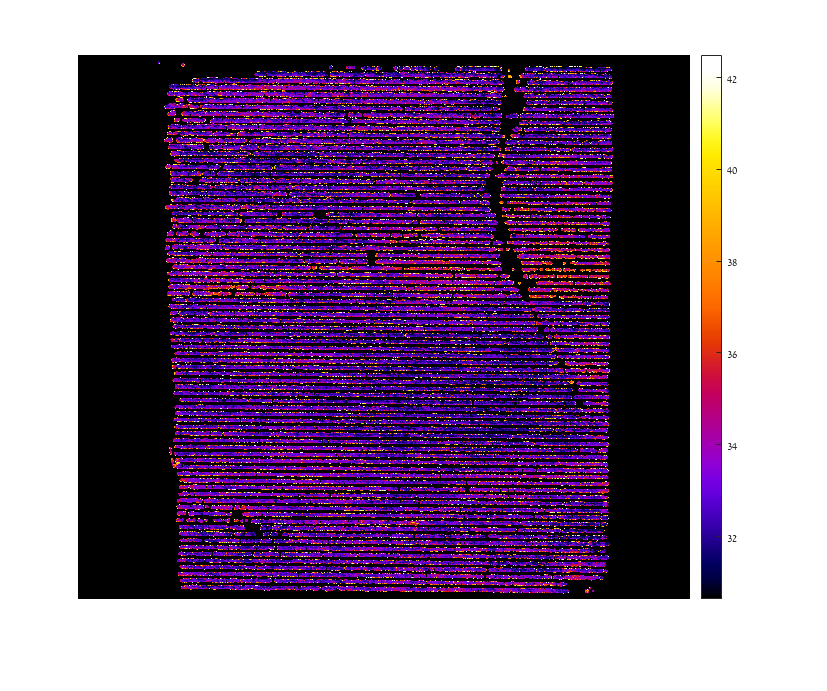

        Site_Name=repelem(cellstr(Site),size(Trees,1))';
        row = dataWithRows.rownum;
        Tree_num= dataWithRows.Tree_num;
        Area = dataWithRows.Area;
     
        %  AirTemp = dataWithRows.AirTemp;
        mean_First_ring = dataWithRows.mean_First_ring ;
        mean_second_ring = dataWithRows.mean_second_ring;
        mean_three_ring = dataWithRows.mean_three_ring;
        mean_core = dataWithRows.mean_core;
        
        median_First_ring = dataWithRows.median_First_ring ;
        median_second_ring = dataWithRows.median_second_ring;
        median_three_ring = dataWithRows.median_three_ring;
        median_core = dataWithRows.median_core;
    
        [centroidY,centroidX]= map2pix(tfwBigImage,Longitude,Latitude);
       RTK_Num= dataWithRows.RTK_Num;
        Plots_Data=table(RTK_Num,Site_Name,Plot,cluster_number,Area,row,Tree_num,...
            Longitude,Latitude,...
            mean,min,prctile5,max,prctile95,std,Std_plot,MTD,median,...
            skewness,kurtosis,IQR,MAD,Meanci,centroidY,centroidX,...
            Diff_median_of_plot, Diff_mean_of_plot, Diff_std_of_plot,...
            Diff_median_of_row,Diff_mean_of_row,Diff_std_of_row,...
            mean_First_ring,mean_second_ring,mean_three_ring,mean_core,...
            median_First_ring,median_second_ring,median_three_ring,median_core);
        All_Plots_Data=vertcat(All_Plots_Data,Plots_Data);
        Alltemperatures = vertcat(Alltemperatures,temperatures);
       %}
    end 
  
end 

%{mean_prctile33%}

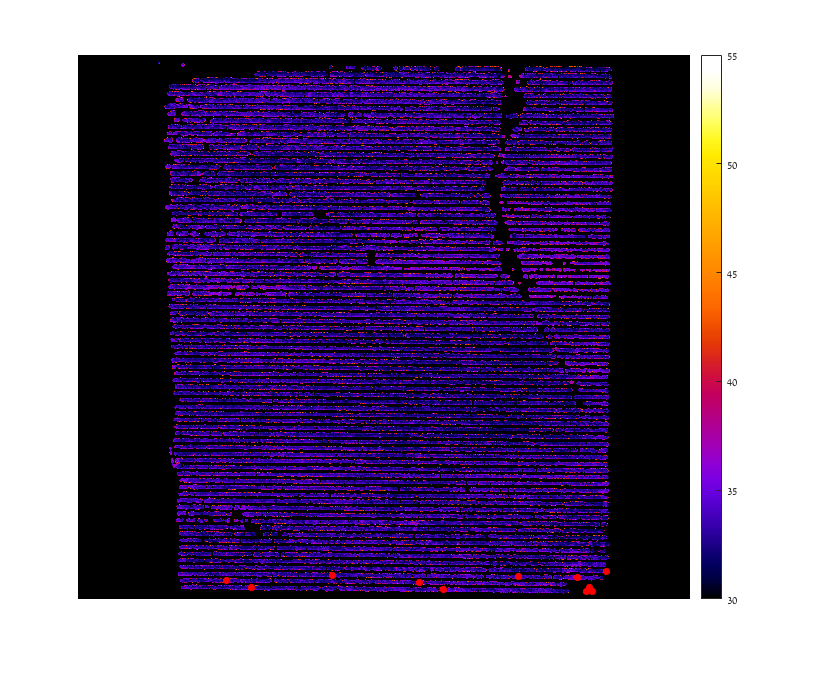

imshow(plot_new,[30 55]);
        colormap(cmap_mat);
        colorbar(); 
        hold on
       
        plot(dataWithRows.CentroidX(dataWithRows.rownum==1),dataWithRows.CentroidY(dataWithRows.rownum==1),'r*','LineWidth',3,'MarkerSize',5)

director=(['C:\Users\Stav\Desktop\school\2\Research\hohoba\results\']);

writetable(All_Plots_Data,[director  Site 'DataForModel.xls']);

CWSI calculation

%{
Twet = prctile(Alltemperatures,5);
All_Plots_Data.CWSI = ((All_Plots_Data.mean_prctile33-Twet)./(5+All_Plots_Data.AirTemp-Twet));
[mean_CWSI_Row,gname] = grpstats(All_Plots_Data.CWSI,{All_Plots_Data.Plot,All_Plots_Data.row},{@mean,'gname'});
dataWithCWSI = table(char(gname(:,1)),int8(str2double(gname(:,2))),mean_CWSI_Row,'VariableNames',{'Plot','row','mean_CWSI_Row'});
All_dataWithCWSI= innerjoin(dataWithCWSI,All_Plots_Data);
All_dataWithCWSI = movevars(All_dataWithCWSI,'RTK_Num','Before','Plot');
All_dataWithCWSI.CWSI_minus_CWSI_of_row = All_dataWithCWSI.mean_CWSI_Row -All_dataWithCWSI.CWSI;
All_Plots_Data = removevars(All_dataWithCWSI,{'mean_CWSI_Row'});
%}

%Relevants_trees= All_Plots_Data(find(All_Plots_Data.RTK_Num>0),:);
%Malfunctions=Malfunctions(find(Malfunctions.RTK_Num>0),:);
%Data=join(Relevants_trees,Malfunctions,'Keys','RTK_Num');
%AllData=outerjoin(All_Plots_Data,Malfunctions,'Keys','RTK_Num');

%writetable(AllData,[director Site '_AllDataWithRows'  '.xls']);
%writetable(AllData,[director  Site 'KedmaDataForModel.xls']);

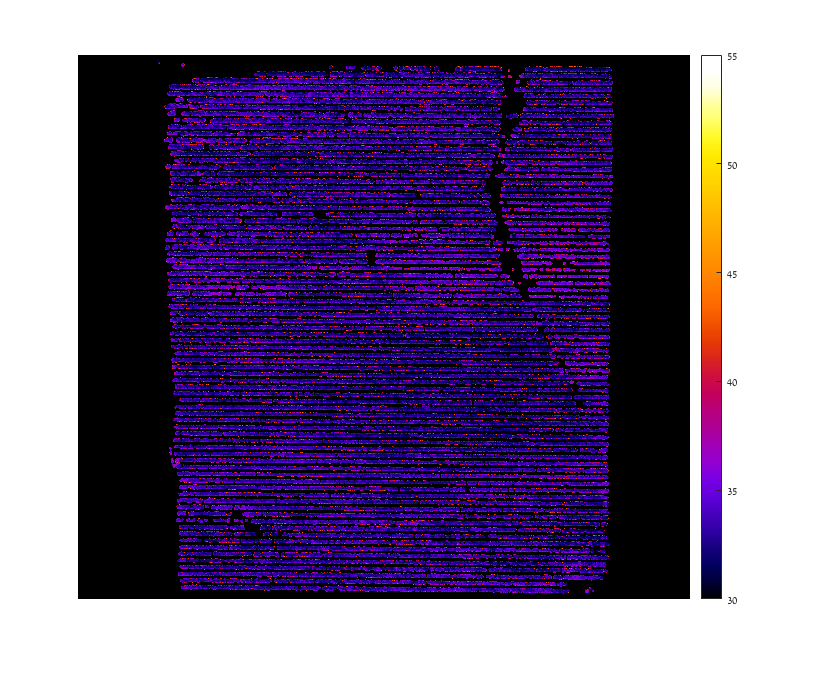

imshow(plot_new,[30 55]);
        colormap(cmap_mat);
        colorbar(); 
        hold on

       
        plot(dataWithRows.pos1(dataWithRows.rownum ==11),dataWithRows.pos2(dataWithRows.rownum ==11),'r*','LineWidth',3,'MarkerSize',30)

Error using tabular/dotParenReference (line 76)
Unrecognized table variable name 'pos1'.

        plot(dataWithRows.pos1(dataWithRows.rownum ==13),dataWithRows.pos2(dataWithRows.rownum ==13),'b*','LineWidth',3,'MarkerSize',30)
        plot(dataWithRows.pos1(dataWithRows.rownum ==12),dataWithRows.pos2(dataWithRows.rownum ==12),'g*','LineWidth',3,'MarkerSize',30)

 

Big_image_path=(['C:\Users\Stav\Desktop\school\2\Research\Networks example\Thermal_transparent_reflectance_grayscale']);
tfw_file=strcat(Big_image_path,'.tfw');
tif_file=strcat(Big_image_path,'.tif');
tif_file=double(imread(tif_file))/100;
%tfw=worldfileread(tfw_file,'planar',size(tif_file));
val=tif_file(find(tif_file>0));
maxT= prctile(val,82);
minT=prctile(val,2);
%tif_file(tif_file>maxT-7)=-100;
imshow(tif_file,[minT-1 maxT]);

colormap(cmap_mat);
colorbar(); 
hold on

%[Malfunctions_Y,Malfunctions_X]= map2pix(tfw,Malfunctions.Longitude,Malfunctions.Latitude);
%h1= gscatter(Malfunctions_X,Malfunctions_Y, Malfunctions.Type,'crk','.',28)
%h1= scatter(AllData.centroidX,AllData.centroidY,28,"cyan") 

legend("Leak","Clog","Control",'Location','northeastoutside')


classified as leak

%legend('Real Clog','Real Leak','Classified Correctly','Classified as Leak',...
%    'Classified as Normal','Location','southoutside','FontSize',10)
%h = scatter(All_Plots_Data_X,All_Plots_Data_Y,20,'green',"filled");
%h = scatter(Malfunctions_X,Malfunctions_Y,20,'white',"filled");

hold off 